# HDL Coder Optimization in Simulink

*Version:* R2025b

Use area and speed optimizations in HDL Coder™ to save resources and improve the timing of your design on the target FPGA device. The optimizations do not change the functional behavior of your algorithm but can optimize certain resources in your design, introduce latency, or cause difference in sample rates.

The example used throughout this demo is a **multi-module phase shift generator**.

Throughout the example, the configuration is fixed as follows:

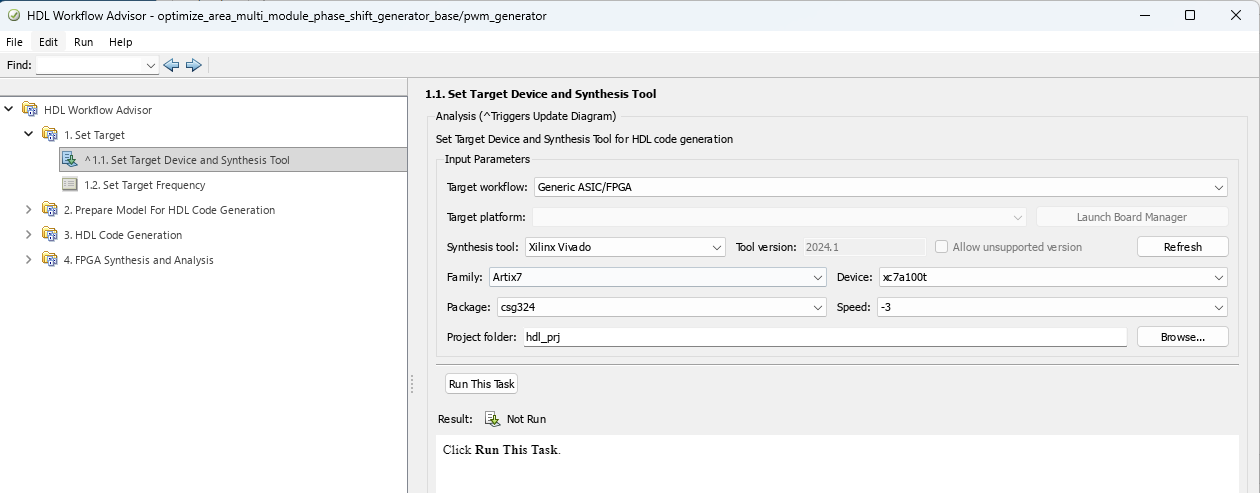

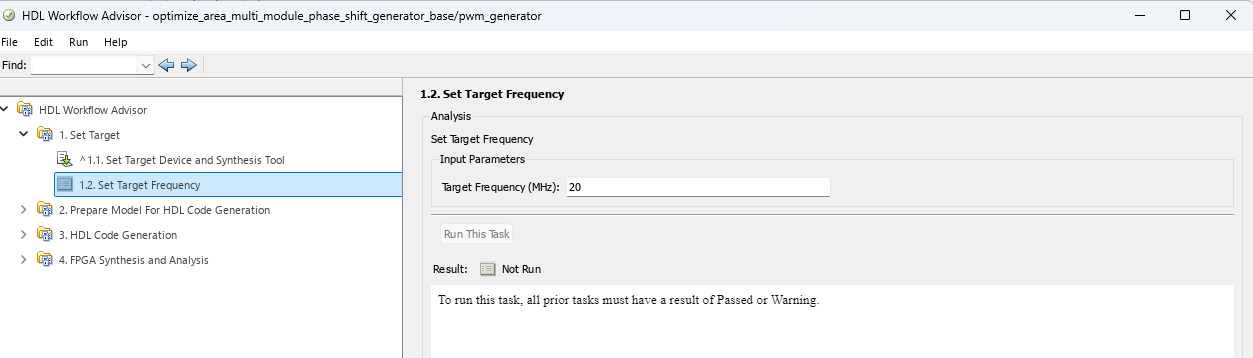

## Base Model

The base model implements the algorithm using fundamental Simulink building blocks, serving as our performance baseline before any optimization is applied.

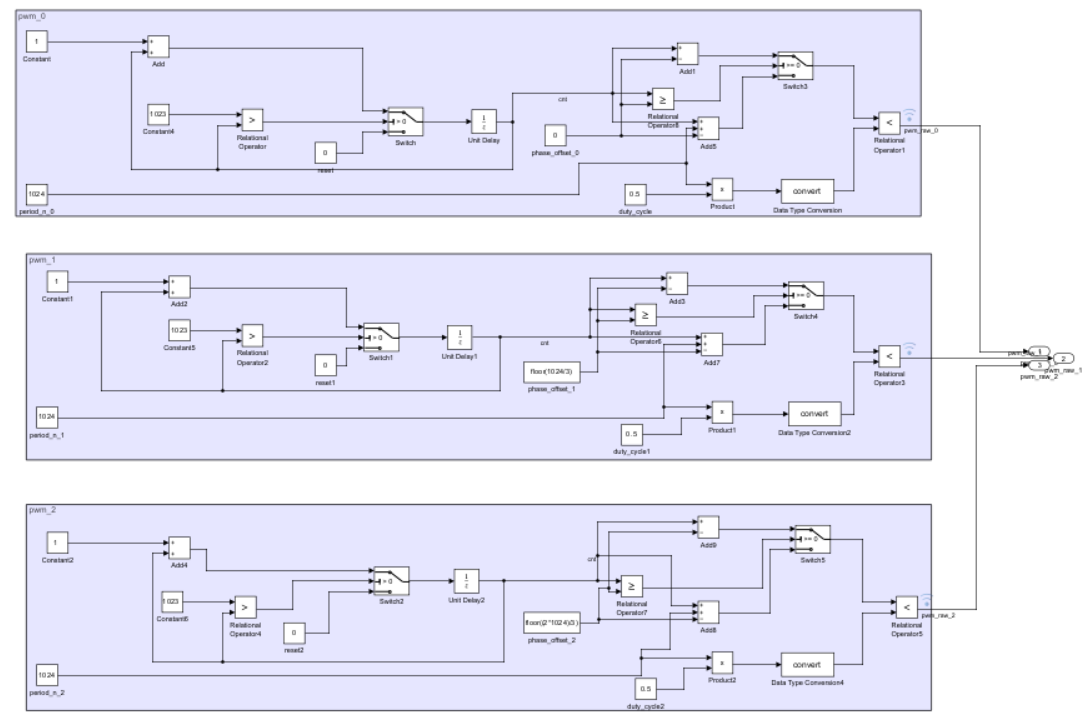

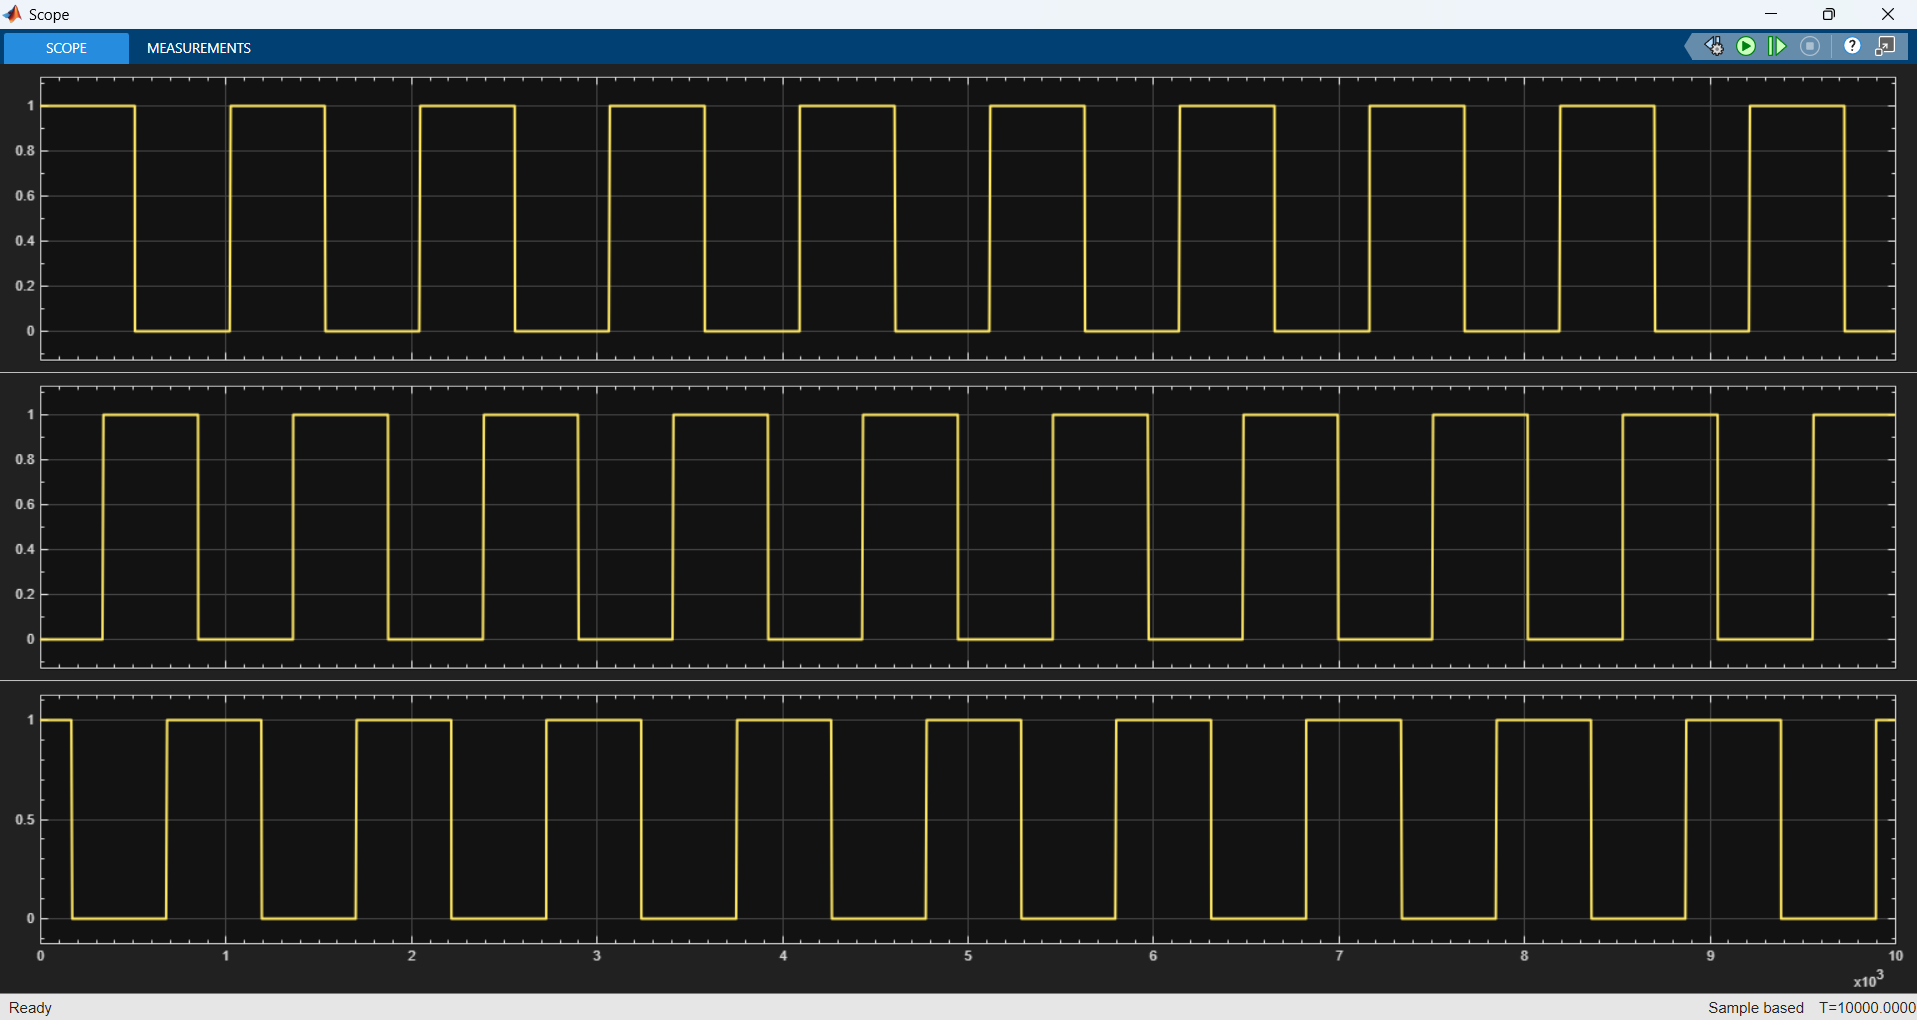

open multi_module_phase_shift_generator_base.slx

**Resource Estimation**

**Critical Path Estimation**

## **Optimization - Timing**

### **Adaptive Pipelining**

Adaptive pipelining automatically inserts pipeline registers across the design to reduce the critical path delay. This comes at the cost of additional registers, as reflected in the increased register count.

open adaptive_pipelining_multi_module_phase_shift_generator_base.slx

**Resource Estimation**

**Critical Path Estimation**

### Input/Output Pipelining + Distributed

This approach combines input/output pipelining with distributed pipelining to achieve a similar critical path improvement as adaptive pipelining, but with a more efficient use of registers overall.

open input_output_distributed_pipelining_multi_module_phase_shift_generator_base.slx

**Resource Estimation**

**Critical Path Estimation**

## **Optimization - Area**

### **Resource Sharing**

Resource sharing reduces the number of multipliers by time-multiplexing shared hardware across multiple operations. While this significantly cuts multiplier usage, it introduces additional multiplexers and registers to manage the scheduling, and slightly increases the critical path delay.

open resource_sharing_multi_module_phase_shift_generator_base.slx

**Resource Estimation**

**Critical Path Estimation**

## **Built-in Counter Model**

This model replaces the basic Simulink counter logic with HDL Coder's built-in Counter block, achieving the same functional output with a substantially reduced register count and fewer multiplexers, demonstrating the resource efficiency gains from using HDL-aware primitives.

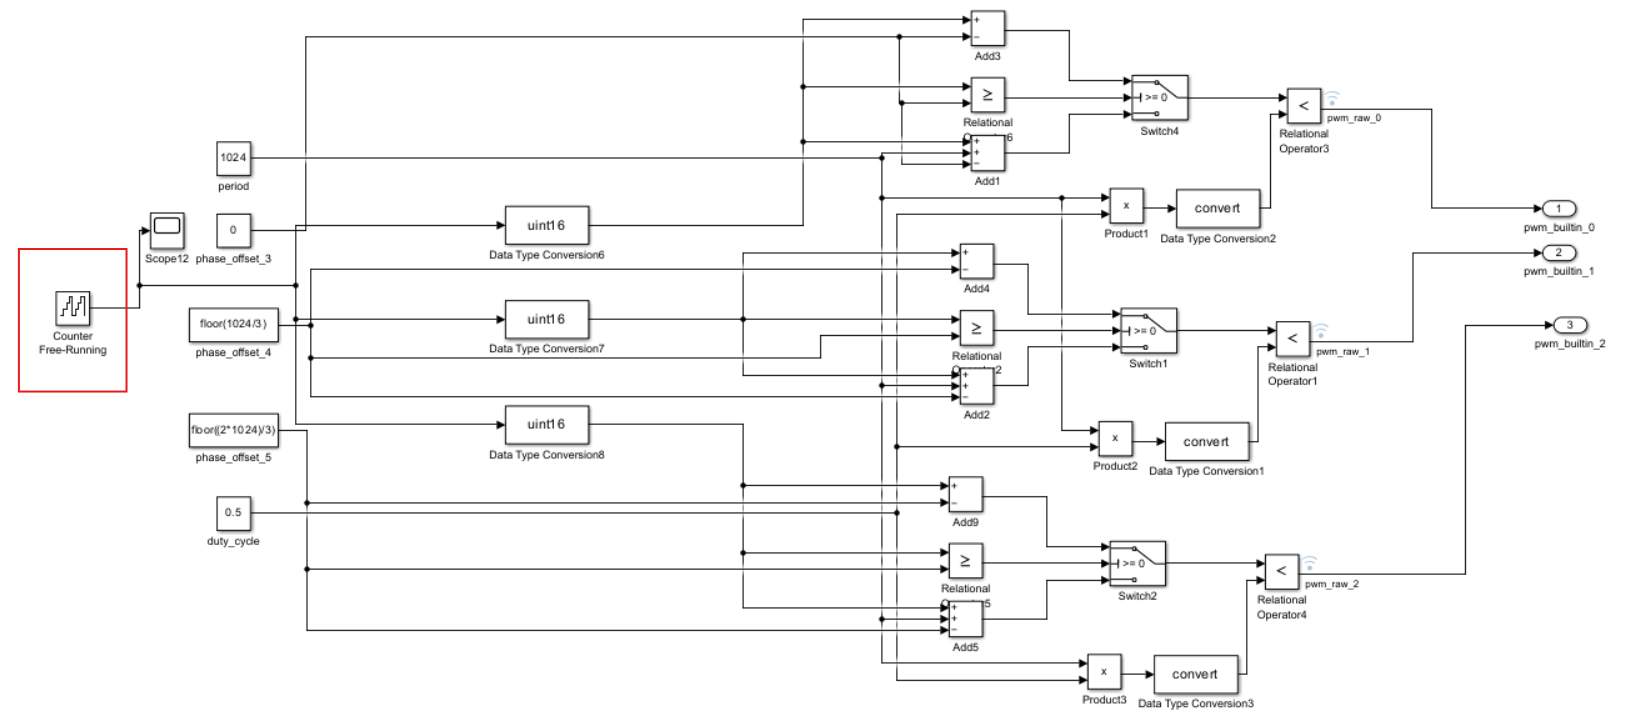

open multi_module_phase_shift_generator_built_in_counter.slx

**Resource Estimation**

**Critical Path Estimation**

## **Built-in PWM Model**

This model uses HDL Coder's built-in PWM block to generate a comparable output. However, since this block only supports the `double` data type, the model must be configured to use **native floating-point** when generating HDL code. This results in significantly higher resource consumption across all categories, making it less suitable for area-constrained designs.

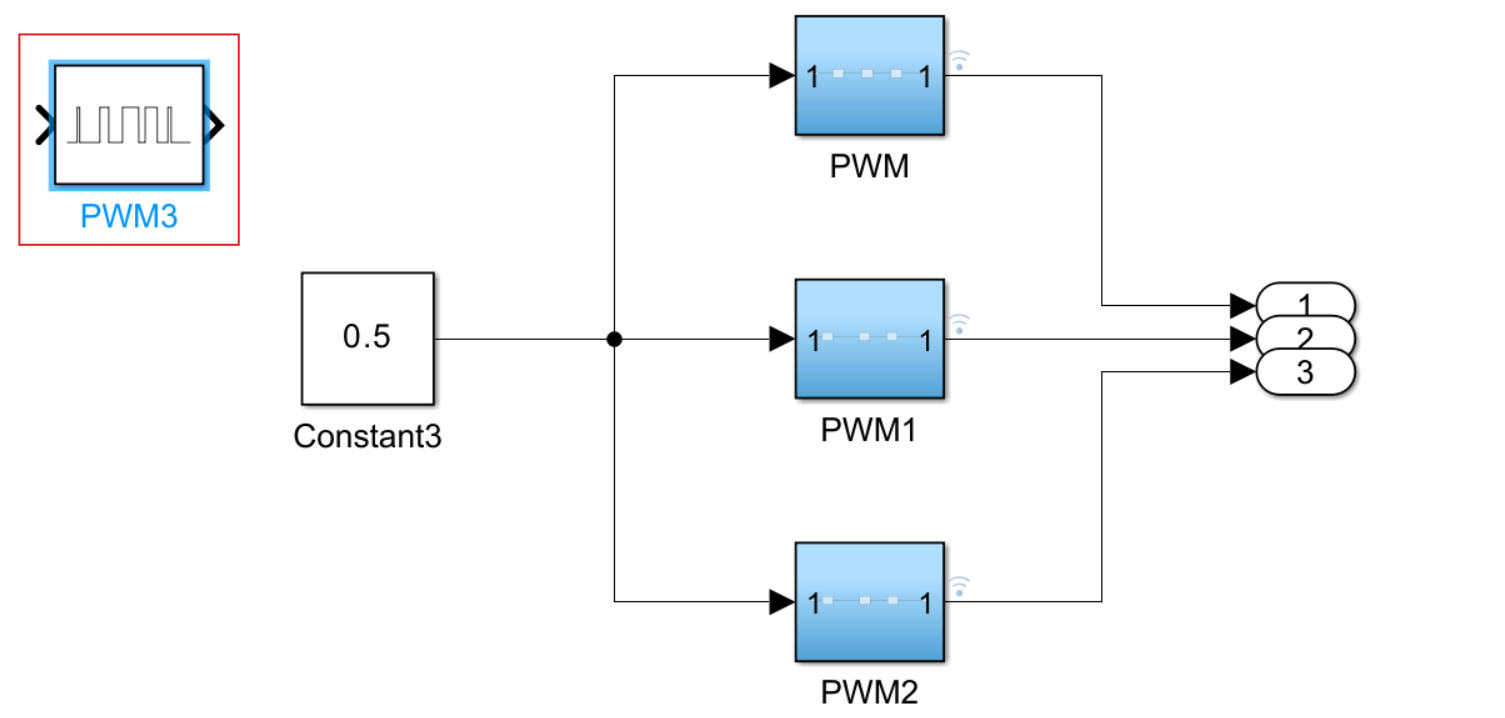

open multi_module_phase_shift_generator_built_in_pwm.slx

**Resource Estimation**

**Critical Path Estimation**

## **Summary**

#### Model Comparison - Resource Estimation

#### Model Comparison - Critical Path Estimation

## Reference

[1] [Speed and Area Optimizations in HDL Coder](https://www.mathworks.com/help/hdlcoder/ug/introduction-to-speed-and-area-optimizations-in-hdl-coder.htm)